# TITLE

## Introduction

In the field of hydrology and hydraulics, understanding flow of water in open channels is an important topic. Gaining a better understanding of this topic is essential to solving problems related to water resource management. This study was conducted by researchers at the Federal University of Ceará in Brazil, a country with vast water resources. Because of the vast river system in Brazil, flooding due to intense precipitation or control structures breaking is a very present issue. Around the world, flooding is among the most frequently occurring natural disasters and results in devastating property damage and human casualties (Mujumdar, 2001). In this paper, the authors seek to build a hydrodynamic model of flood wave propagation in natural rivers using the Saint Venant equations. Building predictive models like this can help to prevent future loss of life and property damage due to flooding in the future. Being able to estimate floods and the effect of stream channels on floods, aids in the design of effective protective structures (Keskin, 1997).

There are two equations that make up the Saint Venant's equations that describe 1-dimensional flow in an open channel, a continuity equation and a momentum equation. The equations this model is based on have been modeled previously using various different techniques. Common techniques for solving simplifications to the full momentum equation include kinemmatic wave routing (Agiralioglu, 1981) and diffusion approximation (Aken and Yen, 1981). However there are concerns about the accuracy of these models (Keskin, 1997). There have also been several models of the Saint Venant's equations created without any simplification for cylindrical and and irregular river cross sections (CITATION). The biggest draw back to these models is the large amount of effort and computation that must be done. 

## Equations

### Fundamental Physical Process and Derivation of Equations

The fundamental physical processes being explored are the hydraulic and hydrologic behavior in bodies of water, specifically, flood wave propagation in natural rivers. The Saint Venant’s equations are the basic equations that describe wave propagation in an open channel. While there are also 2-dimensional versions of these equations, the 1-dimensional Saint Venant’s equations describe flood mechanics and are used to build this model. There are two main equations: 

          (∂Q/∂x)+(∂A/∂t) = 0                                                              (1)

          (∂Q/∂t)+(∂(Q^2/A)/∂x)+gA((∂y/∂x)-S0)+gASf = 0                 (2)

Equation 1 is the continuity equation, which expresses the conservation of water volume. Equation 2 is the momentum equation, which provides the balancing between forces and momentum change rates. To create this model, another form of the momentum equation was derived using equations 1, 2, and 3:

          (∂Q/∂t)+α(∂Q/∂x)+β = 0                                                       (3)

Where,

          α=2(Q/A)+(((gA/B)-(Q^2/A^2))/((Q/A)((5/3)-(4R/3B)))         (4)

and

          β = g*A*(((Q^2*n^2)/(A*R^(4/3)))-S0);                                 (5)

### Boundary and Initial Conditions

#### *Initial conditions:*

#### *Boundary conditions:*

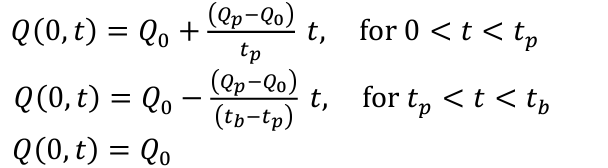

### Simplifications and assumptions

- Flow is considered 1-Dimensional

- Distribution of pressure vertically is hydrostatic

- Water is incompressible and homogenous

- Density is constant through time and space

- The shape of the channel is a rectangle and constant

## Numerical Methods

Utilizing Advection with an upwind scheme to model flood propogation. 

This method is used because of the complexity of the system. With so many variable and need to show how small changes impact on a larger scale, the advection method is good for modeling this. Things like the slope of the river, river shape, friction, velocity, etc.. all impact the what ultimately happens in reality. Advection-diffusion allows us to add on motifiers that we need in order to properly convey changes and see what variables are causing the largest changes. This is important on a larger scale as the model is deal with trying to understand how flood waves propogate in a river. 

## CODE

### Simulation 1: Inflow hydrograph and computed outflow hydrographs at different distances

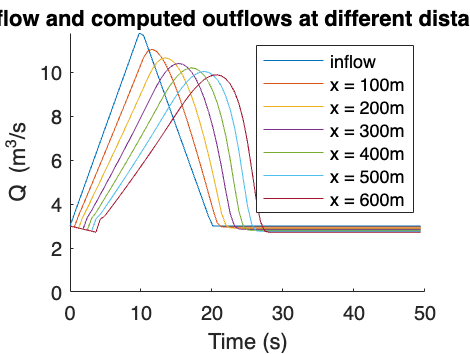

%parameters:
L = 2000; %length of channel, meters (m)
b = 5;  %width of the bottom of the channel, meters (m)
S0 = 0.0005;  %slope of the bottom of the channel
n = 0.0138; %Manning's roughness coefficient for the bottom of the channel
g = 9.8; %acceleration due to gravity, m^2/s
h = 3.5; %water depth, meters (m)

%set up time and space vectors
dt = 0.61; % delta t, seconds (s)
    %at this dt(.61), the most mass is conserved and the solution remains stable 
t = 0:dt:50; %time vector
dx = 100; % delta a, meters (m)
x = 0:dx:L; %space vector

%pre-allocate Q matrix and A matrix
%Discharge (Q) matrix:
Q = zeros(length(x), length(t));
%set up boundary conditions for Q
Q0 = 3; %base flow of inflow hydrograph, m^3/s
Qp = 12; %peak flow of inflow hydrograph, m^3/s
tp = 10; %time to peak flow of inflow hydrograph, seconds
tb = 20; %total time to return to base flow after peak flow
mask = t < 10;
Q(1,mask) = Q0 + ((Qp-Q0)/(tp))*t(mask);
Q(:, 1) = Q0;
mask = t >= 10 & t < 20; 
Q(1,mask) = Q0 - ((Qp-Q0)/(tb-tp))*(t(mask)-tb);
mask = t >= 20;
Q(1,mask) = Q0;

% Cross Section Area (A) matrix:
A = ones(length(x), length(t));
A(:,1) = b*h; %inital cross section area calculated from given width and estimated water depth of channel, meters (m)

% matrix with the same dimensions to keep track of Courant value. 
C = zeros(length(x), length(t));
    % because alpha is changing, the Courant value is not constant and so we
    % need to keep track of it as we vary the time step in order to
    % maintain stablility

%solve the equations
for j = 1:length(t)-1
    for i = 2:length(x)-1 

        R = A(i,j)/(2*h+b); %R is the hydraulic radius
        alpha = 2*(Q(i,j)/A(i,j)) + (((g*A(i,j))/b)+(Q(i,j)/A(i,j))^2)/((Q(i,j)/A(i,j))*((5/3)-(4/3)*(R/b)));
        beta = g*A(i,j)*(((Q(i,j)^2*n^2)/(A(i,j)*R^(4/3)))-S0);
        
        C(i,j) = (dt/dx) * alpha; %need to keep this below 1 to remain stable

        Q(i, j+1) = Q(i,j) - (dt/dx) * alpha * (Q(i,j)-Q(i-1,j)) + beta*dt;
        A(i, j+1) = A(i,j) - (dt/dx) * (Q(i, j)-Q(i-1,j));
    end
end

%plot inflow and outflow
figure(1);
hold on
for y = 1:7
    plot(t,Q(y,:));
end
ylim([0, inf]);
xlabel('Time (s)');
ylabel('Q (m^3/s');
legend('inflow', 'x = 100m', 'x = 200m', 'x = 300m', 'x = 400m', 'x = 500m', 'x = 600m');
title('Inflow and computed outflows at different distances');

### Simulation 2: Unstable Figure 1

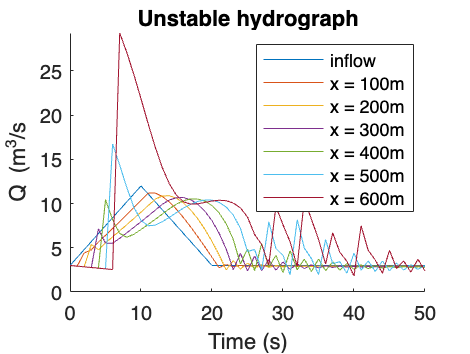

[Qu, tu] = waveProp(0.0005, 0.0138, 1);

figure;
hold on
for y = 1:7
    plot(tu,Qu(y,:));
end
ylim([0, inf]);
xlabel('Time (s)');
ylabel('Q (m^3/s');
legend('inflow', 'x = 100m', 'x = 200m', 'x = 300m', 'x = 400m', 'x = 500m', 'x = 600m');
title('Unstable hydrograph')

### Simulation 3: Variation of S0

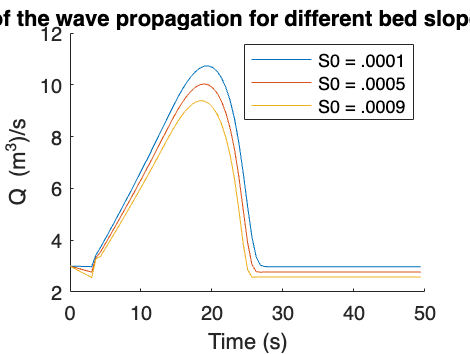

QVec = [];
n = .0138;
dt = 0.61;
for S0 = [.0001 .0005 .0009]
    [Q, t] = waveProp(S0,n,dt);
    QVec = [ QVec; Q(6,:)];
end

figure 
hold on
plot(t, QVec(1,:))
plot(t, QVec(2,:))
plot(t, QVec(3,:))
xlabel('Time (s)')
ylabel('Q (m^3)/s')
title('Wave propagation for different bed slope (S0) at x = 600m')
legend('S0 = .0001', 'S0 = .0005', 'S0 = .0009')

### Simulation 4: Variation of n

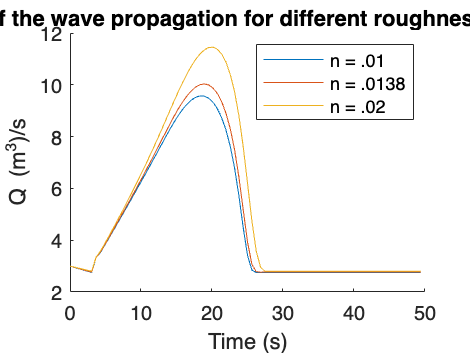

QVec = [];
S0 = 0.0005;
dt = 0.61;
for n = [.01 .0138 .02]
    [Q, t] = waveProp(S0,n, dt);
    QVec = [ QVec; Q(6,:)];
end

figure 
hold on
plot(t, QVec(1,:));
plot(t, QVec(2,:));
plot(t, QVec(3,:));
xlabel('Time (s)');
ylabel('Q (m^3)/s');
title('Wave propagation for different roughness (n) at x = 600m');
legend('n = .01', 'n = .0138', 'n = .02');

## Results

#### Simulation 1

The first simulation we ran plotted discharge, Q, over time for different positions along the channel. 

*What simulations did you run with the model?*

*Describe the results.*

*How do the results compare with any known solutions, or data?*

*How do the results change with different methods, time steps, grid spacing, or model parameters?*

*What did the model tell you about the process you were studying?*

*How could the model be improved in terms of methods used or processes included?*

*At least 4 figures describing results *

*Have all axes labeled*

*Variables have units*

*Everything is readable*

*Colors, lines, contours, etc. are all easy to discern*

## References

## Simulation Function

function [Q, t] = waveProp(S0, n, dt)
L = 2000;
b = 5;
g = 9.8;
h = 3.5;

%set up time and space vectors
t = 0:dt:50; 
dx = 100;
x = 0:dx:L;

% Pre-allocate Q matrix and A matrix
% Discharge (Q) matrix:
Q = zeros(length(x), length(t));
% set up boundary conditions for Q
Q0 = 3;
Qp = 12;
tp = 10;
tb = 20;
mask = t < 10;
Q(1,mask) = Q0 + ((Qp-Q0)/(tp))*t(mask);
Q(:, 1) = Q0;
mask = t >= 10 & t < 20; 
Q(1,mask) = Q0 - ((Qp-Q0)/(tb-tp))*(t(mask)-tb);
mask = t >= 20;
Q(1,mask) = Q0;
% Cross Section Area (A) matrix:
A = ones(length(x), length(t));
A(:,1) = b*h;
% matrix with the same dimensions to keep track of Courant value
C = zeros(length(x), length(t));

%solve the equations
for j = 1:length(t)-1
    for i = 2:length(x)-1 
        R = A(i,j)/(2*h+b);
        alpha = 2*(Q(i,j)/A(i,j)) + (((g*A(i,j))/b)+(Q(i,j)/A(i,j))^2)/((Q(i,j)/A(i,j))*((5/3)-(4/3)*(R/b)));
        beta = g*A(i,j)*(((Q(i,j)^2*n^2)/(A(i,j)*R^(4/3)))-S0);
       
        C(i,j) = (dt/dx) * alpha;

        Q(i, j+1) = Q(i,j) - (dt/dx) * alpha * (Q(i,j)-Q(i-1,j)) + beta*dt;
        A(i, j+1) = A(i,j) - (dt/dx) * (Q(i, j+1)-Q(i-1,j+1));
    end
end
end